clear;
data = readtable("data.xlsx")

data = 8760×25 table
    meter_serial            meter_desc                   tstamp              date            day           time          tou         week_number            impwh             difference_imp_kwh     ptot      stot     expwh    difference_exp_kwh    pftot      md       qtot      epoch_timestamp        interval_start       waste    meter_id    tou_id    season_profile_id    season_class_id    tariff_id
    ____________    __________________________    ____________________    ___________

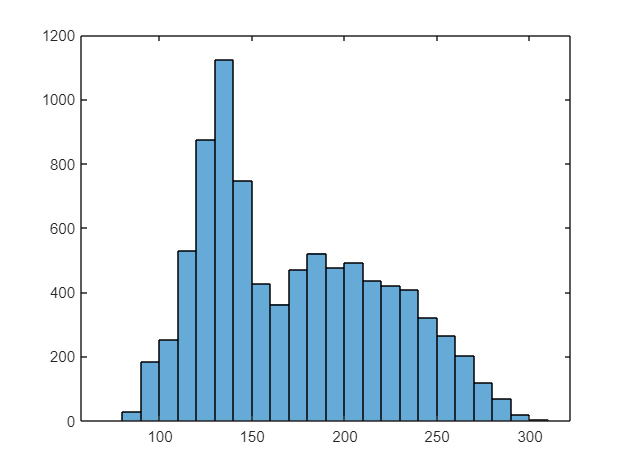


%Remove data with no information  
data = removevars(data, ["meter_serial", "meter_desc", "expwh","difference_exp_kwh","interval_start", "waste", "meter_id", "tariff_id", "impwh","stot", "pftot","md","qtot","difference_imp_kwh","epoch_timestamp","season_class_id","season_profile_id","day","week_number"]);

missingElements = ismissing(data, {string(missing),NaN});
rowsWithMissing = any(missingElements, 2);

missingValuesTable = data(rowsWithMissing,:);

data = rmmissing(data);

data.day = day(data.date, "iso-dayofweek");


low_time = 0.29;
up_time = 0.75;
weekDayCondition = (data.day ~= 6) & (data.day ~= 7) ;
SatCondition     = (data.day == 6);
SunCondition     = (data.day == 7);
wrkHrsCondition  = (data.time >= low_time) & (data.time <= up_time) & (data.day ~= 6) & (data.day ~= 7);
dayTimeCondition = (data.time >= low_time) & (data.time <= up_time);

data.weekDay    = double(weekDayCondition);
data.Sat         = double(SatCondition);
data.Sun        = double(SunCondition);
data.wrkHr      = double(wrkHrsCondition);
data.dayTime    = double(dayTimeCondition);

data.tou = categorical(data.tou);
data = [data onehotencode(data(:,"tou")) ];

data = removevars(data,["date","time","day","tou"]);

                            
% Fill outliers
[data,outlierIndices5,thresholdLow5,thresholdHigh5] = filloutliers(data,...
    "linear","percentiles",[4.75 100],"DataVariables","ptot");

figure
histogram(data.ptot)

data

data = 8754×11 table
           tstamp            ptot     tou_id    weekDay    Sat    Sun    wrkHr    dayTime    Off-Peak    Peak    Standard
    ____________________    ______    ______    _______    ___    ___    _____    _______    ________    ____    ________

    01-Jan-2022 00:00:00    96.855      3          0        1      0       0         0          1         0         0    
    01-Jan-2022 01:00:00    97.053      3          0        1      0       0         0          1         0         0    
    01-Jan-2022 02:00:00    97.229      3          0        1      0       0         0          1         0         

summary(data)

Variables:

    tstamp: 8754×1 datetime

        Values:

            Min       01-Jan-2022 00:00:00
            Median    02-Jul-2022 08:30:00
            Max       31-Dec-2022 23:00:00

    ptot: 8754×1 double

        Values:

            Min         79.12 
            Median     165.15 
            Max        304.46 

    tou_id: 8754×1 double

        Values:

            Min          2    
            Median       3    
            Max          4    

    weekDay: 8754×1 double

        Values:

            Min          0    
            Median       1    
            Max          1    

    Sat: 8754×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Sun: 8754×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    wrkHr:

%Need to get rid of date time. Think Imma keep Hour

data.day = day(data.tstamp, "dayofyear");
data.time = hour(data.tstamp);

data =  removevars(data,["tstamp"]);

dataArr = table2array(data);

data = transpose(dataArr)

data =    96.8550   97.0530   97.2290   96.8590   98.0180   98.0220  150.6020  153.3490  156.5230  157.5200  157.2490  161.1520  156.0560  159.6760  159.6780  162.3190  166.3760  165.7520  162.3050  109.8990   99.8460   99.7760   98.9990   99.4140   98.8240   98.2780   98.8290   97.7290   97.8810   98.7990   95.8990   97.0980   97.0830   96.8930   97.5180   98.0110   97.6760   96.9490   97.6150   99.7220   98.0330   96.8460   96.4870   96.0730   96.6260   97.4760   96.7280   96.5570   98.0680   97.1830
    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000  

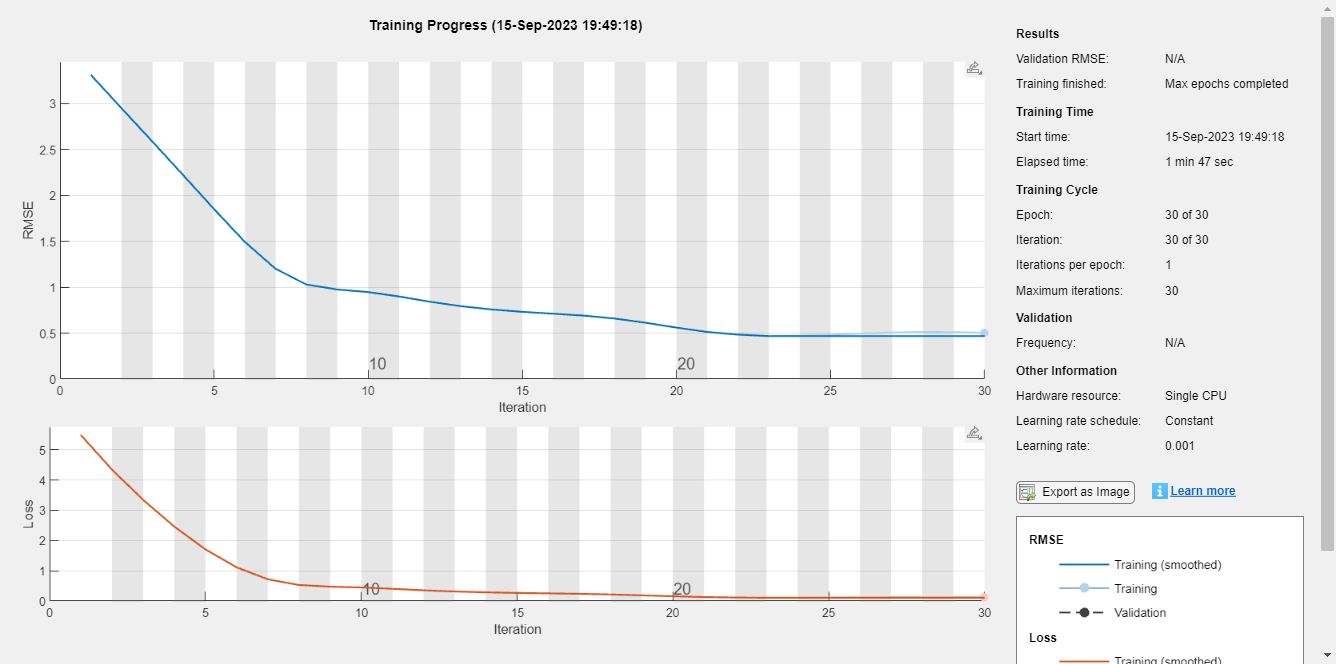

data=normalize(data);


numObservations = length(data);
idxTrain = 1:floor(0.9*numObservations);
idxTest = floor(0.9*numObservations)+1:numObservations;
dataTrain = data(:,idxTrain);
dataTest = data(:,idxTest);
%Prepare Data for Training
%To forecast the values of future time steps of a sequence, specify the targets as the training sequences with values shifted by one time step. In other words, at each time step of the input sequence, the LSTM neural network learns to predict the value of the next time step. The predictors are the training sequences without the final time step.

    X = dataTrain(:,:);
    XTrain = X(:,1:end-1);
    TTrain = X(:,2:end);

%For a better fit and to prevent the training from diverging, normalize the predictors and targets to have zero mean and unit variance. When you make predictions, you must also normalize the test data using the same statistics as the training data. To easily calculate the mean and standard deviation over all sequences, concatenate the sequences in the time dimension.


numChannels = 12; 

layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)
    regressionLayer];


options = trainingOptions("adam", ...
    MaxEpochs=30, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);


net = trainNetwork(XTrain,TTrain,layers,options);